# **LABORATORIO 2 ROBOTICA**

**UNIVERSIDAD NACIONAL DE COLOMBIA**

### **Aristides Daniel Cantero Castillo**

### **Farid Alexis Estepa Quintero **

### **William Andrés Castillo Bautista**

**15 de diciembre del 2021**

**Robot ABB IRB 15000**

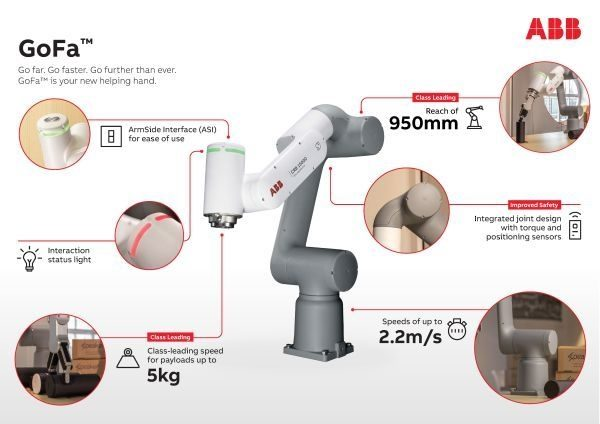

**Tabla de parámetros DH.**

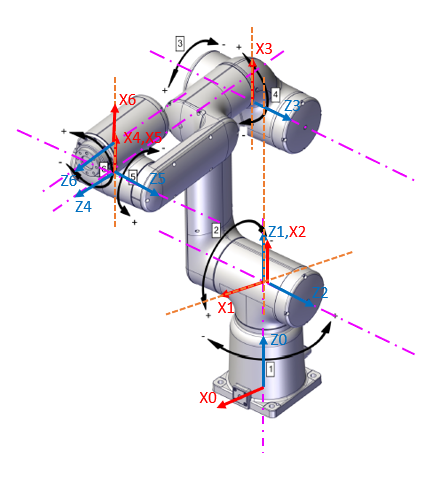

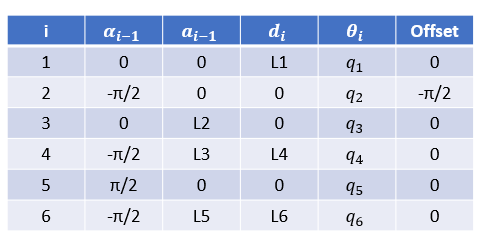

clc
syms theta_1 theta_2 theta_3 theta_4 theta_5 theta_6  
L1=0.265; L2=0.444; L3=0.110; L4=0.470; L5=0.080; L6=0.037;

%Se crean links, el primer parametro de la funcioón correspode al tipo de articulación. 
% En este caso todas son de tipo rotacional. Después se ingresan los
% parámetros alpha, a, d y offset. Luego se indica que los parametros
% corresponden a MDH. Finalmente se indican los rangos de operación.

L(1) = Link('revolute','alpha', 0,    'a', 0,   'd',L1,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha', -pi/2,    'a', 0,   'd',0,   'offset', -pi/2,   'modified', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha', 0,    'a', L2,   'd',0,   'offset', 0,   'modified', 'qlim',[-3.92699 1.48353]);
L(4) = Link('revolute','alpha', -pi/2,    'a', L3,   'd',L4,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha', pi/2,    'a', 0,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha', -pi/2,    'a', L5,   'd',L6,   'offset', 0,   'modified', 'qlim',[-pi pi]);
% Se articulan todos los links y se le asigna un nombre a todo el sistema
Robot_ABB = SerialLink(L,'name','ABB CRB 15000'); 
%Se plotea el robot, para ciertos ángulos theta.
Robot_ABB.plot([0,0,0,0,0,0],'workspace',[-0.5 0.5 -0.5 0.5 -0.1 1],'scale',0.5,'noa', 'view',[140 20])

### 3. Haga uso de las funciones del RVC para hallar la cinemática inversa de su robot asignado y compruebe los resultados del punto anterior. Ya que existen varias funciones en el *Toolbox *explique:

### ¿Cuál es la diferencia entre estas funciones?

### ¿Cuál debe usar para su robot y por qué? (Revise la documentación del *Toolbox*)  

clc

Robot_ABB = SerialLink(L,'name','ABB CRB 15000'); 

Target = [1 0 0 0.5
          0 1 0 0.5
          0 0 1 0.5
          0 0 0 1];
qSolve = Robot_ABB.ikunc(Target); 	%inverse kinematics using optimisation

q1 = qSolve(1)*(180/pi)

q1 = 45.0000

q2 = qSolve(2)*(180/pi)

q2 = 45.6755

q3 = qSolve(3)*(180/pi)

q3 = -19.0581

q4 = qSolve(4)*(180/pi)

q4 = -3.8479e-06

q5 = qSolve(5)*(180/pi)

q5 = -116.6174

q6 = qSolve(6)*(180/pi)

q6 = 135.0000

Robot_ABB.plot([q1 q2 q3 q4 q5 q6],'workspace',[-0.5 0.5 -0.5 0.5 -0.1 1],'scale',0.5,'noa', 'view',[140 20])

qSolve = Robot_ABB.ikine(Target); 	%inverse kinematics using iterative numerical method

q1 = qSolve(1)*(180/pi)

q1 = 45.0000

q2 = qSolve(2)*(180/pi)

q2 = 45.6755

q3 = qSolve(3)*(180/pi)

q3 = -19.0581

q4 = qSolve(4)*(180/pi)

q4 = -6.6918e-07

q5 = qSolve(5)*(180/pi)

q5 = -116.6174

q6 = qSolve(6)*(180/pi)

q6 = 135.0000

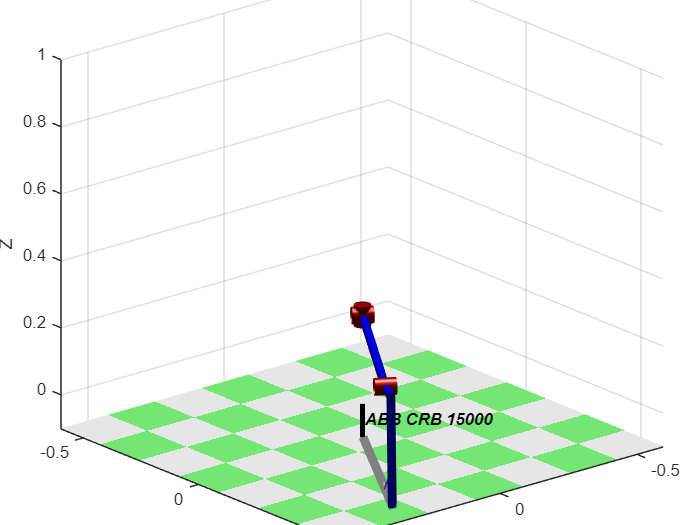

Robot_ABB.plot([q1 q2 q3 q4 q5 q6],'workspace',[-0.5 0.5 -0.5 0.5 -0.1 1],'scale',0.5,'noa', 'view',[140 20])